Задание 1

a = input('Введите вектор:');
fliplr(a)

ans =      3     2     1


Задание 2

a = input('Введите вектор:');
a1 = a(mod(a,2)==0)

a1 = 2

a2 = a(mod(a,2)==1)

a2 =      1     3


Задание 3

a = input('Введите вектор:');
sum(a(a<0))

ans = 0

Задание 4

a = input('Введите вектор:');
geo = geomean(a)

geo = 1.8171

for i = 1:length(a)
    if abs(a(i)*100/geo) > 130
        a(i) = geo;
    end
end
a

a =     1.0000    2.0000    1.8171


Задание 5

a = input('Введите вектор:');
mi = min(a);
ma = max(a);
for i = 1:length(a)
    if a(i) == ma
        a(i) = mi;
    end
end
a

a =      1     2     1


Задание 6

a = input('Введите вектор:');
disp("a > 0: " + length(a(a>0)));

a > 0: 3


disp("a = 0: " + length(a(a==0)));

a = 0: 0


disp("a < 0: " + length(a(a<0)));

a < 0: 0


Задание 7

A = [2 3 3; 4 2 3; 6 5 6];
b = [8; 7; 7];
x1 = A\b

x1 = 	1.0e+16 *

    0.9007
    1.8014
   -2.4019


cond(A) 

ans = 4.2540e+16

C = [A b];
D = rref(C);
x2 = D(:,end)

x2 =      0
     0
     1


checkx1 = A*x1

checkx1 =      0
     0
     0


checkx2 = A*x2

checkx2 =      3
     3
     6


Задание 8

t = [0; 0.1; 0.2; 0.3; 0.4; 0.5];
y = [4.25; 3.95; 3.64; 3.41; 3.21; 3.04];
A = [exp(-t) t];
x = A\y;
a = x(1)

a = 4.2478

b = x(2)

b = 0.9070

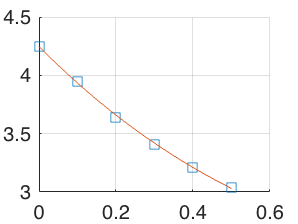

figure; hold on; grid on;
plot(t, y, 's');
fplot(@(t) a.*exp(-t) + b.*t, [0 0.5])

Задание 9

A = [1 2 3; 3 4 5];
b = [2; 2];
x = A\b

x =    -1.0000
         0
    1.0000


isequal(round(A*x), b) 

ans = logical
   1


Задание 10

A = [2 3 3; -2 -3 -3];
b = [8; 7];
[x, r] = linsolve(A,b)

x =          0
    0.1667
         0


r = 1

cond(A)

ans = 1.4937e+16

Задание 11

A = [2 3 3; -2 -3 -3];
b = [8; 7];
[q, r] = qr(A);
x = (r\q'*b)

x =          0
    0.1667
         0


Задание 12

A = [2 4 5; 3 6 7; 8 5 2];
[x, y] = eig(A);
for i = 1:length(x)
    vec = x(:,i)
end

vec =    -0.4610
   -0.6709
   -0.5809


vec =    -0.3792
    0.7849
   -0.4900


vec =    -0.3627
   -0.4491
    0.8165


for i = 1:length(x)
    p = y(i,i)
end

p = 14.1226

p = 0.1810

p = -4.3035

A*x(:,1)

ans =    -6.5099
   -9.4744
   -8.2038


y(1,1)*x(:,1)

ans =    -6.5099
   -9.4744
   -8.2038
